**Analyse des paterns d'activations lors des mouvements fonctionelles**

clc; clear all; 

% Ajout de la bibliothèque btk  
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition sujet
subjects = {'TM24'};
%'MF01', 'TF02', 'YL03', 'RF05', 'AP06'
%'TD07', 'IS08', 'LC09', 'MP10', 'PK11'
%'JM13', 'GD14', 'LD15', 'LM16', 'JV18'
%'EG19', 'MG20', 'LB21', 'AP22', 'SC23'
%'TM24', 'EG25', 'RL26'
nb_subjects = length(subjects);

% Définition des muscles pour les côtés droit et gauche
muscles_R = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'RLATD', 'RSERRA'};
muscles_L = {'LDELTA', 'LDELTM', 'LDELTP', 'LTRAPM', 'LTRAPS', 'LLATD', 'LSERRA'};
nb_muscles = length(muscles_R);

% Demande de sélection du côté à analyser
side_choice = input('Choisissez le côté à analyser (1: Droite, 2: Gauche): ');
if side_choice == 1
    muscles_selected = muscles_R;
    side_label = 'Droit';
else
    muscles_selected = muscles_L;
    side_label = 'Gauche';
end

% Définition des labels pour les tâches
functional_labels = {... 
    'Porter les mains à la bouche', ...
    'Toucher le haut de la tête', ...
    'Porter les mains le plus haut possible au-dessus de la tête', ...
    'Porter les mains le plus haut possible le long de la colonne vertébrale'};

analytic_labels = { 
    'Flexion (élévation sagittale)', ...
    'Abduction (élévation coronale)', ...
    'Rotation externe (abduction 0°)', ...
    'Rotation interne (abduction 0°)'};

nb_functional = length(functional_labels);
nb_analytic = length(analytic_labels);

% Paramètres EMG
fs = 2000;
[b, a] = butter(4, [15, 475] / (fs/2), 'bandpass');
rms_window = round(0.250 * fs);
num_points = 1000;
time_normalized = linspace(0, 1, num_points);

% Nouvelle association Muscle -> Tâche Analytique définie manuellement
assigned_analytics = [1, 2, 2, 2, 2, 4, 2];

% Initialisation des MVC des tâches analytiques
mvc = zeros(nb_muscles, 1);

% Calcul du MVC basé sur la tâche analytique assignée
for subj_idx = 1:nb_subjects
    for m = 1:nb_muscles
        analytic_idx = assigned_analytics(m);
        
        fileName_analytic = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
            '%s-%s-20240101-PROTOCOL01-ANALYTIC%d-.c3d'], ...
            subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, analytic_idx);
        
        c3dH_analytic = btkReadAcquisition(fileName_analytic);
        analogs_analytic = btkGetAnalogs(c3dH_analytic);
        
        muscle_name = muscles_selected{m};
        if isfield(analogs_analytic, muscle_name)
            signal = analogs_analytic.(muscle_name);
            signal_filtered = filtfilt(b, a, signal);
            signal_abs = abs(signal_filtered);
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
            mvc(m) = max(emg_rms);
        end
    end
end

% Sélection d'une tâche fonctionnelle unique
selected_functional = input('Choisissez une tâche fonctionnelle (1-4): ');

% Initialisation des matrices pour stocker les maximas des trois tiers
top3_max = zeros(nb_muscles, 3);
top3_times = zeros(nb_muscles, 3);

% Indices des trois tiers du temps normalisé
idx1 = 1:round(num_points/3);
idx2 = round(num_points/3)+1:round(2*num_points/3);
idx3 = round(2*num_points/3)+1:num_points;

% Création de la figure
figure;
hold on;
title(sprintf('Activité musculaire (%s) - %s', side_label, functional_labels{selected_functional}));
xlabel('Temps normalisé');
ylabel('EMG (% MVC)');
colors = lines(nb_muscles);

for subj_idx = 1:nb_subjects
    fileName_functional = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, selected_functional);
    
    c3dH_functional = btkReadAcquisition(fileName_functional);
    analogs_functional = btkGetAnalogs(c3dH_functional);
    
    for m = 1:nb_muscles
        muscle_name = muscles_selected{m};
        
        if isfield(analogs_functional, muscle_name)
            signal = analogs_functional.(muscle_name);
            signal_filtered = filtfilt(b, a, signal);
            signal_abs = abs(signal_filtered);
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
            
            % Normalisation du temps
            time_original = linspace(0, 1, length(emg_rms));
            emg_interp = interp1(time_original, emg_rms, time_normalized, 'spline');

            % Normalisation par le MVC associé à la tâche prédéfinie
            emg_normalized = (emg_interp / mvc(m)) * 100;
            
            % Extraction des maximas dans chaque tiers
            [max1, idx_max1] = max(emg_normalized(idx1));
            [max2, idx_max2] = max(emg_normalized(idx2));
            [max3, idx_max3] = max(emg_normalized(idx3));
            
            % Stockage des valeurs et indices
            top3_max(m, :) = [max1, max2, max3];
            top3_times(m, :) = [idx1(idx_max1), idx2(idx_max2), idx3(idx_max3)];
            
            % Tracé du signal
            plot(time_normalized, emg_normalized, 'Color', colors(m, :), 'LineWidth', 1.2, 'DisplayName', muscle_name(2:end));

            % Ajout des marqueurs pour les trois maximas
            plot(time_normalized(top3_times(m, :)), top3_max(m, :), 'ro', 'MarkerFaceColor', 'r');

            % Ajout d'annotations pour afficher les valeurs maximales
            for k = 1:3
                text(time_normalized(top3_times(m, k)), top3_max(m, k), ...
                    sprintf('%.1f', top3_max(m, k)), 'FontSize', 10, ...
                    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'r');
            end
        end
    end
end

% Affichage des trois valeurs maximales sous forme de tableau
fprintf('\nMaximas par tiers du temps pour chaque muscle :\n');


Maximas par tiers du temps pour chaque muscle :


disp(array2table(top3_max, 'VariableNames', {'Début', 'Milieu', 'Fin'}, 'RowNames', muscles_selected));

              Début     Milieu     Fin  
              ______    ______    ______

    RDELTA    29.384    29.532    25.896
    RDELTM    8.9637    9.6275    10.502
    RDELTP    11.886    11.213    11.964
    RTRAPM    6.0664    6.8562      10.1
    RTRAPS     22.67    19.919    19.957
    RLATD     26.441     25.17    25.533
    RSERRA    28.613     25.91    34.214



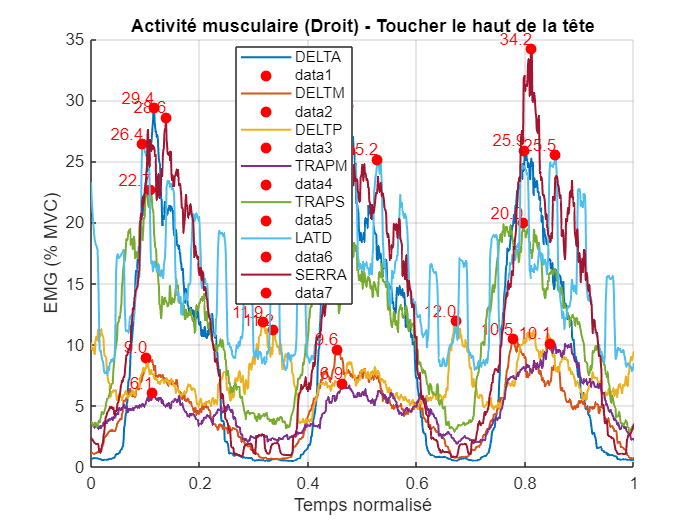


% Ajout des labels et affichage final du graphique
legend('show', 'Location', 'best');
grid on;
hold off;